Rubén Vera Martínez, NIA: 241456

Sara Soriano Rossa, NIA: 240007

**PROBLEM 1**

**a) Apply PCA to the input data. To show the result:**

**    (i) Display the eigenvalues associated to the first 10 principal components.**

**    (ii) Make a scatter plot of the first two principal components, making sure to use different markers to distinguish both samples.**

women = SM22Lab5Female130{:,:};
men = SM22Lab5Male130{:,:};
X = [men women];
X = X';
cov_X = cov(X);
[V, D] = eig(cov_X);
[sorted_D_hat, sorted_indx_hat] = sort(diag(D), 'desc');
sorted_V_hat = V(:, sorted_indx_hat);

% Display 10 first eigenvalues
first_10_eigen = sorted_D_hat(1:10);
fprintf('The first 10 eigenvalues are: ');

The first 10 eigenvalues are: 

fprintf('%g, ', first_10_eigen(1:end));

4045.97, 905.606, 424.937, 312.724, 241.735, 196.997, 166.536, 146.643, 111.07, 97.3785, 

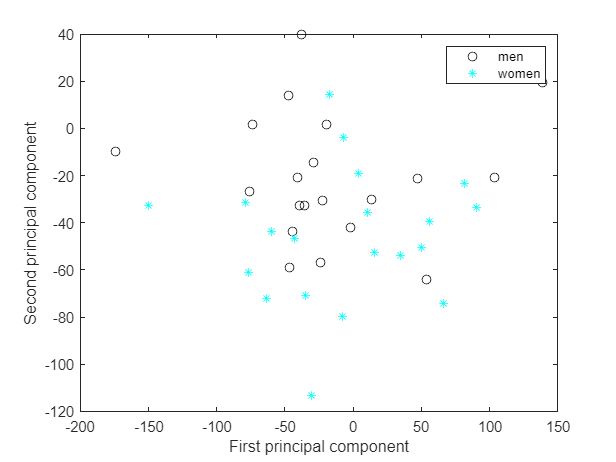


Y =  sorted_V_hat(:,1:2)' * (X - mean(X, "all"))';

plot(Y(1,1:20), Y(2,1:20), 'o', 'Color', 'black');          % men
xlabel('First principal component');
ylabel('Second principal component');
hold on
plot(Y(1, 21:40), Y(2, 21:40), '*', 'Color', 'cyan');      % women
legend({'men', 'women'})
hold off

**b) Use permutation tests to determine how many Principal Components are significant (in the sense indicated above). To this end you should perform at least R = 1000 rounds of permutations of the data matrix. For each of these rounds, you must permute the entries independently for each dimension, decompose the resulting matrix into eigenvalues and eigenvectors, and keep track of the eigenvalues (adequately sorted). After this, you will have R replicates for the magnitude of each of your eigenvalues under the null hypothesis of randomness in the data. Use these replicates to determine a p-value for each of the eigenvalues (and their associated Principal Components). Clearly indicate the number of components k that can be considered significant at α = 0.05 according to your analysis.**

n = length(X);
B = 1e4;
p = 260;
theta_rep = zeros(p, B);
rs_indx = zeros(p, n);
theta_hat = sorted_D_hat;
rng(0);
for j=1:B
    for i=1:p
        rs_indx(i, :) = ceil(n*rand(1,n));
    end
    X_boot = X(rs_indx);
    cov_x_boot = cov(X_boot');
    [P,D] = eig(cov_x_boot);
    [sorted_D_rep, sorted_indx_rep] = sort(diag(D), 'desc');
    theta_rep(:,j) = sorted_D_rep;
end

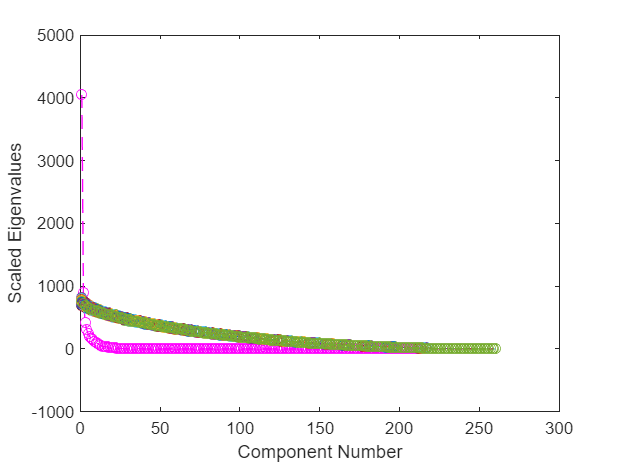


h.figure = figure('Color','White');
h.axes = axes(); 
h.plot = plot(theta_hat(:, 1),'o--','Color','magenta');
xlabel('Component Number');
ylabel('Scaled Eigenvalues');
hold on
for i=1:B
    h.plot = plot(theta_rep(:, i),'o--');
end
hold off


alpha = 0.05;
n_against_h0 = zeros(1, p);
p_value = zeros(1, p);
for i = 1:p
    n_against_h0(i) = length(find(theta_rep(i,:) >= theta_hat(i)));
    p_value(i) = n_against_h0(i)/B;
end
p_value

p_value =      0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


Viendo el vector p-values y el scree plot, se puede ver claramente que k = 2, es decir, las principales componentes significativas son las 2 primeras. En el caso del vector p-value esto lo sabemos ya que en la posición 1 y 2 el p-value es menor a alpha y en el resto de dimensiones, el valor es mayor.

**c) Estimate the percentage of variance retained by the k significant components that you have obtained in (b). Use bootstrap to estimate a 95% confidence interval of the percentage of variance retained by those k components.**

theta_hat = (sorted_D_hat(1) + sorted_D_hat(2)) / sum(sorted_D_hat);
n = size(X,1);
B = 1e4;
theta_rep= zeros(1, B);
rs_indx = zeros(1, n);
rng(0);
for j=1:B
    rs_indx = ceil(n*rand(1,n));
    X_boot = X(rs_indx,:);
    cov_x_boot = cov(X_boot);
    [P,D] = eig(cov_x_boot);
    [sorted_D_rep, sorted_indx_rep] = sort(diag(D), 'desc');
    sorted_D_rep = diag(sorted_D_rep);
    theta_rep(1,j) = (sorted_D_rep(1, 1) + sorted_D_rep(2, 2)) / sum(sorted_D_rep, "all");
end

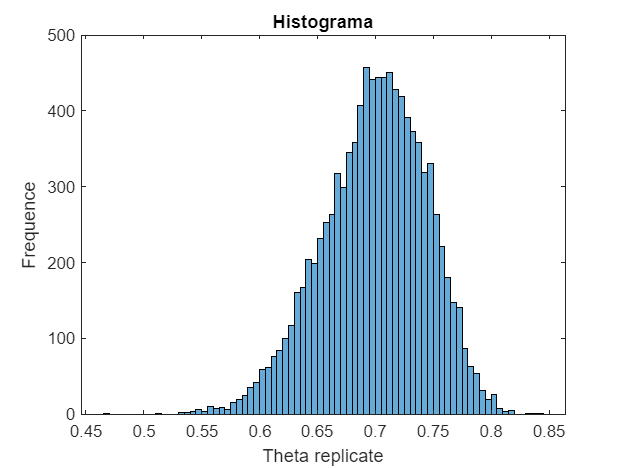

histogram(theta_rep);
hold on
title('Histograma');
xlabel('Theta replicate'); 
ylabel('Frequence');
hold off

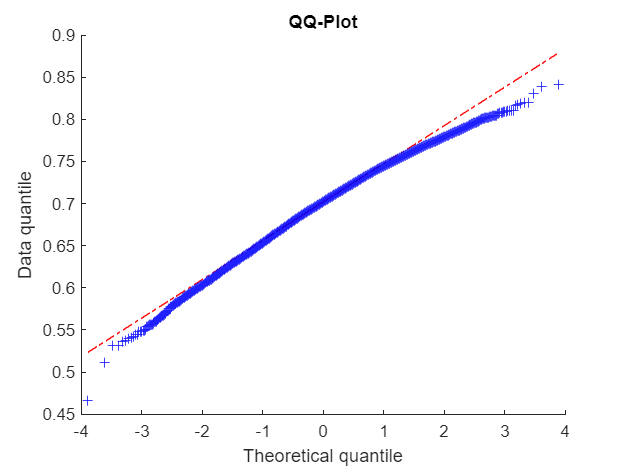


qqplot(theta_rep); % No rechazamos normalidad
hold on
title('QQ-Plot');
xlabel('Theoretical quantile'); 
ylabel('Data quantile');
hold off


% Usamos percentile-based intervals

alpha = 0.05;
theta_biasCorrected = 2*theta_hat-mean(theta_rep);
theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_biasCorrected - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_biasCorrected-theta_rep_sort(round((B)*(alpha/2)));]

conf_interval =     0.5682    0.7412


**PROBLEM 3**

**a) Using the similarity scores from the provided file, convert them into a distance matrix D and apply MDS. From the obtained coordinates Y in the embedding space, display the resulting configuration using the first 2 dimensions (i.e. those associated to the highest eigenvalues). According to the dimensional theory of emotions, the resulting configuration should display an approximately circular arrangement. Make sure to indicate the emotion label for each of the displayed points (e.g. with different colors).**

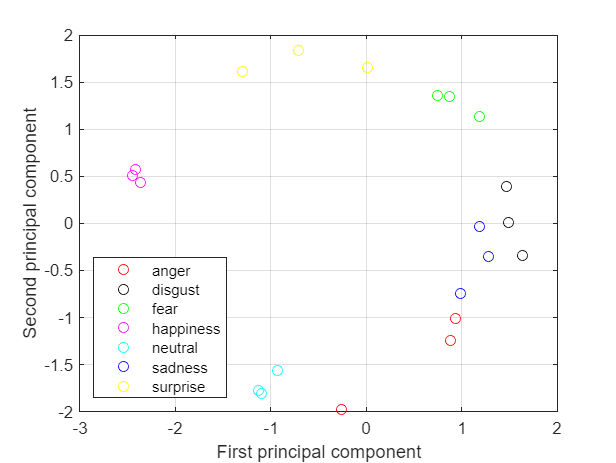

C = SM22Lab5Similarities{:,:};
n = length(C) / 3;
delta = zeros(n);
for i=1:21
    for j=1:21
        delta(i,j) = sqrt(C(i,i) - 2 * C(i,j) + C(j,j));
    end
end
A = -(1/2) * delta.^2;
H = eye(21) - (1/21) * ones(21,21);
B = H*A*H;
[V, D] = eig(B);
n_D = length(D);
D_positive = D(D>0);
n_D_p = length(D_positive);
V_positive = zeros(n_D, n_D_p);
j = 1;
for i=1:n_D
    if D(i, i) > 0
        V_positive(:, j) = V(:, i);
        j = j + 1;
    end
end

[sorted_D, sorted_indx] = sort(D_positive, 'desc');
sorted_V = V_positive(:, sorted_indx);
sorted_D = diag(sorted_D);
Y = sorted_V * sqrt(sorted_D);

Y_2pc = Y(:, 1:2)';
plot(Y_2pc(1, 1:3), Y_2pc(2,1:3), 'o', 'Color', 'red');          % anger
xlabel('First principal component');
ylabel('Second principal component');
hold on
plot(Y_2pc(1, 4:6), Y_2pc(2, 4:6), 'o', 'Color', 'black');       % disgust
plot(Y_2pc(1, 7:9), Y_2pc(2, 7:9), 'o', 'Color', 'green');     % fear
plot(Y_2pc(1, 10:12), Y_2pc(2, 10:12), 'o', 'Color', 'magenta');     % happiness
plot(Y_2pc(1, 13:15), Y_2pc(2, 13:15), 'o', 'Color', 'cyan');     % neutral
plot(Y_2pc(1, 16:18), Y_2pc(2, 16:18), 'o', 'Color', 'blue');     % sadness
plot(Y_2pc(1, 19:21), Y_2pc(2, 19:21), 'o', 'Color', 'yellow');     % surprise
legend({'anger','disgust', 'fear', 'happiness', 'neutral', 'sadness', 'surprise'}, 'Location','southwest');
grid on
hold off

**b) State the null and alternative hypotheses for the research question indicated above.**

Hipótesis:


$$\begin{array}{l}
H_0 :\mu_1 =\mu_2 =\ldotp \ldotp \ldotp =\mu_k \Rightarrow \delta =0\\
H_A :\mu_l \not= \mu_{l^{\prime } } \;\textrm{for}\;\textrm{at}\;\textrm{least}\;\textrm{two}\;l\not= l^{\prime } 
\end{array}$$


donde $\mu$ es la media de la población y k el número de grupos relacionados. En este caso k = 7.

Es decir, la hipotesis nula que no hay una significante diferencia entre las imagenes faciales de cada una de las diferentes emociones. Y la alternativa, que si la hay.

**c) Indicate what method would you use to test the hypotheses stated in (b) using the reduced dimensionality representation from (a). State the assumptions required by the method so that its results are valid. For this problem you do not need to assess whether the assumptions are met: we will assume that they are fulfilled. **

El modelo que nosotros proponemos es MANOVA, las asunciones son:

    1- Each sample $\overrightarrow{X_{l1} } ,\ldotp \ldotp \ldotp ,\overrightarrow{X_{ln_l } }$ for $1\le l\le g$ comes from a normal distribution with $\overrightarrow{\mu_p }$ and $\Sigma_p$.

    2- The random samples for each population are independent of each other.

    3- All populations have the same covariance matrix. 

Asumimos que todas tres asunciones se cumplen. En este caso g=7, ya que tenemos 7 grupos (emociones).

**d) Perform the test selected in (c) at significance level α = 0.05. Clearly indicate your conclusion and your answer to the research question. **

Y_2 = Y_2pc;

x1 = Y_2(:, 1:3);
x2 = Y_2(:, 4:6);
x3 = Y_2(:, 7:9);
x4 = Y_2(:, 10:12);
x5 = Y_2(:, 13:15);
x6 = Y_2(:, 16:18);
x7 = Y_2(:, 19:21);

n_1 = size(x1, 2);
n_2 = n_1;
n_3 = n_1;
n_4 = n_1;
n_5 = n_1;
n_6 = n_1;
n_7 = n_1;

mean_1 = mean(x1, 2);
mean_2 = mean(x2, 2);
mean_3 = mean(x3, 2);
mean_4 = mean(x4, 2);
mean_5 = mean(x5, 2);
mean_6 = mean(x6, 2);
mean_7 = mean(x7, 2);
mean_x = mean(Y_2, 2);

tau_1 = mean_1-mean_x;
tau_2 = mean_2-mean_x;
tau_3 = mean_3-mean_x;
tau_4 = mean_4-mean_x;
tau_5 = mean_5-mean_x;
tau_6 = mean_6-mean_x;
tau_7 = mean_7-mean_x;

error_1 = x1 - mean_1;
error_2 = x2 - mean_2;
error_3 = x3 - mean_3;
error_4 = x4 - mean_4;
error_5 = x5 - mean_5;
error_6 = x6 - mean_6;
error_7 = x7 - mean_7;

g = 7;
B = n_1 * ((tau_1)*transpose(tau_1)) + n_2 * ((tau_2)*transpose(tau_2)) + n_3 * ((tau_3)*transpose(tau_3)) + n_4 * ((tau_4)*transpose(tau_4)) + n_5 * ((tau_5)*transpose(tau_5)) + n_6 * ((tau_6)*transpose(tau_6)) + n_7 * ((tau_7)*transpose(tau_7));
dfB = g-1;
W = error_1*transpose(error_1) + error_2*transpose(error_2) + error_3*transpose(error_3) + error_4*transpose(error_4) + error_5*transpose(error_5) + error_6*transpose(error_6) + error_7*transpose(error_7);
dfW = n_1 + n_2 + n_3 + n_4 + n_5 + n_6 + n_7 - g;
p = size(x1, 1);

estimator = det(W)/(det(W+B));
s = min(p, dfB);
df1 = p * dfB;
df2 = s * (dfW - (p - dfB + 1) / 2)-((p * dfB - 2) / 2);
estimator_f = ((1-estimator^(1/s))/df1)/((estimator^(1/s))/df2)

estimator_f = 53.5585


alpha = 0.05;
crit = finv(1-0.05,df1,df2)

crit = 2.1479


if (estimator_f > crit)
    disp("We reject the null hypothesis at significance level 0.05.");
else 
    disp("We cannot reject the null hypothesis at significance level 0.05.");
end

We reject the null hypothesis at significance level 0.05.


Una vez analizada la hipótesis nula mediante MANOVA, hemos obtenido que el valor del estimador es 53.56 aproximadamente, mientras que el valor crítico es de 2.15 aproximadamente. Al ser el valor estimado mayor al valor crítico, rechazamos la hipótesis nula con un 95% de confianza.

Por lo tanto, la conclusión es que la expresión facial no es la misma para todas las emociones, haciendo post-hoc tests podríamos ver entre cuáles varian significativamente. Con lo realizado solo podemos afirmar que la expresión facial no es similar en todas las emociones.